% Clearing memory, loading classes and input files
clear
addpath('..\..\utilities');
nodepos = load('inputs\u_1_no_bl\Np.mat').Np;
shearrates = load('inputs\u_1_no_bl\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('inputs\u_1_no_bl\Tnode.mat').Tnode;
fillstatus = load('inputs\u_1_no_bl\Fillstatus.mat').Fillstatus;
connectednodes = load('inputs\u_1_no_bl\connectedNodes.mat').connectedNodes;
connectedelements = load('inputs\u_1_no_bl\connectedElements.mat').connectedElements;

% Creating class instances
meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = meshrefiner.calcElementDiffs(elementshearrates);
tempdiffs = meshrefiner.calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);

timestep = 25

timestep = 25

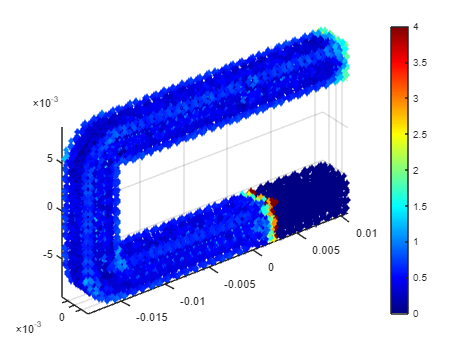

easyvisualizer.plotElementData(elementcoordinates, sheardiffs, timestep, 'no')

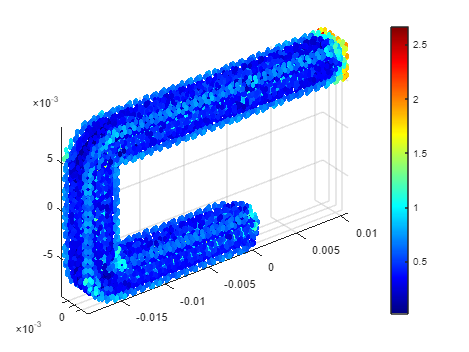

easyvisualizer.plotFillElementData(elementcoordinates, elementfillstatus, sheardiffs, timestep, 'no')

% Calculating highdiffelements by shear diffs
[highsheardiffs_t2, normalsheardiffs_t2, highsheardiffsbytimestep_t2] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 2);
[highsheardiffs_t25, normalsheardiffs_t25, highsheardiffsbytimestep_t25] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 2.5);
[highsheardiffs_t3, normalsheardiffs_t3, highsheardiffsbytimestep_t3] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 3);

% Calculating highdiffelements by temperature diffs
[hightempdiffs_t2, normaltempdiffs_t2, hightempdiffsbytimestep_t2] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 2);
[hightempdiffs_t25, normaltempdiffs_t25, hightempdiffsbytimestep_t25] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 2.5);
[hightempdiffs_t3, normaltempdiffs_t3, hightempdiffsbytimestep_t3] = meshrefiner.calcHighDiffElements(elementfillstatus, tempdiffs, 3);

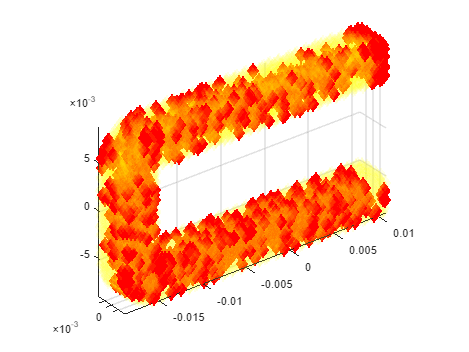

% Visualizing highsheardiffelements
easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t2, normalsheardiffs_t2, 0)

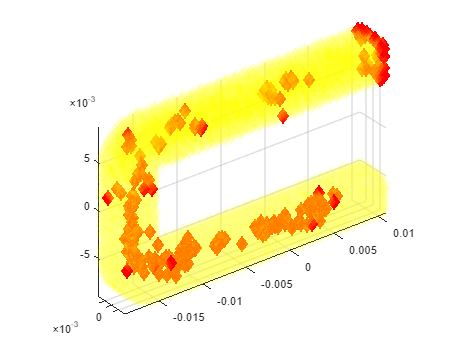

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t25, normalsheardiffs_t25, 0)

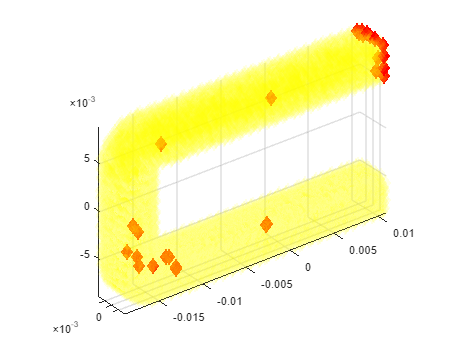

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs_t3, normalsheardiffs_t3, 0)

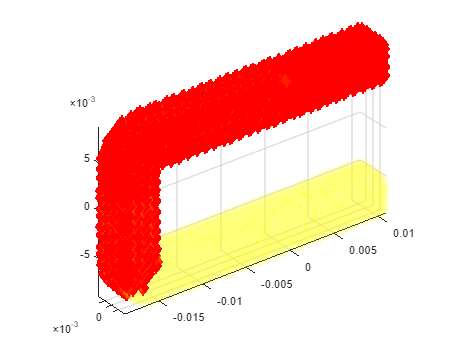


% Visualizing hightempdiffelements
easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t2, normaltempdiffs_t2, 0)

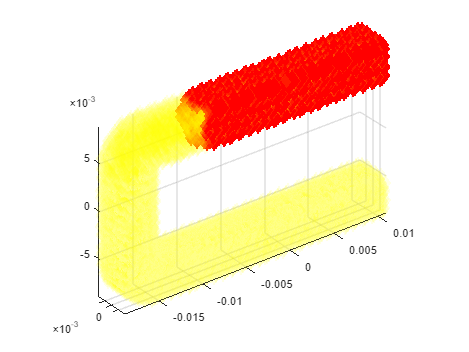

easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t25, normaltempdiffs_t25, 0)

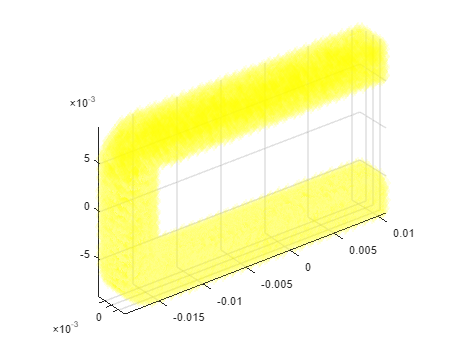

easyvisualizer.plotElementsToRefine(elementcoordinates, hightempdiffs_t3, normaltempdiffs_t3, 0)